# WLAN MAC Basics - Adding QoS Traffic + PCAP Basics

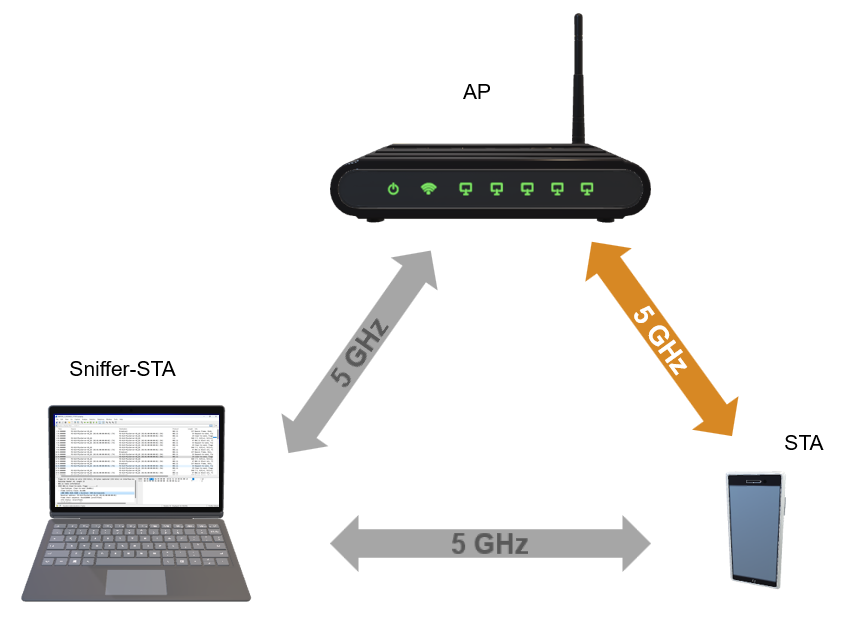

WLAN Network with one AP, one STA, and a Sniffer STA 

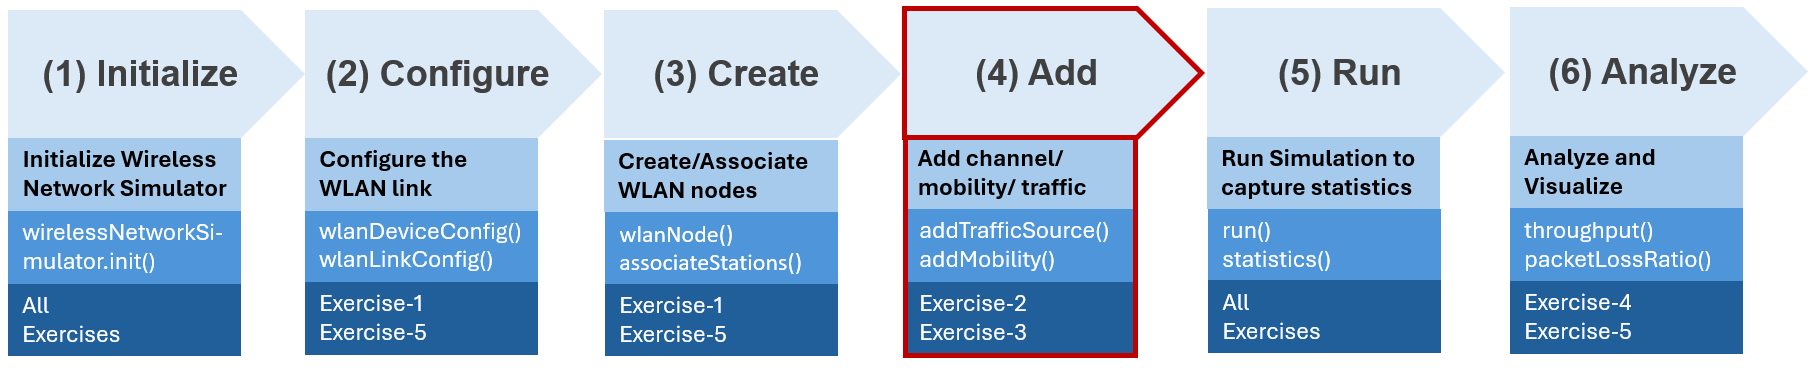

Workflow to perform WLAN Network Modeling 

Copyright 2024-2025 The MathWorks, Inc

### **Please work on the tasks located in the "Exercises" folder and set the "Exercises" folder as the current folder **

### Part 1 : AP generates beacon frames only

- Generate beacon frames only 

- Record PCAP file for post-analysis in Wireshark

### Part 2 : AP generates DL traffic 

- Generate QoS Traffic

- Change the tarffic type from Best effort to video to voice   

- Record PCAP file for post-analysis in Wireshark

### Cleanup

clear;
format shortEng;

#### Make sure PCAP files are saved in a dedicated folder

dir = pwd;
[parentFolder, thisFolder] = fileparts(dir);
dataDir = fullfile(parentFolder,'Data');
if ~exist(dataDir, 'dir')
    mkdir(dataDir)
end
cd(dataDir);

#### Select Traffic Type


trafficType = "Beacon"

### General Settings

bandwidth    = 20e6;
band         = 5;
channel      = 36;
fc           = wlanChannelFrequency(channel,band);

TU              = 1024e-6;
simulationTime  = 100*TU;

### Geography

APPosition  = [0,0,0];
STAPosition = [5,5,0];

plotStations(APPosition, STAPosition, fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

### Create AP

- 802.11n

- beacon sent each 10x TU (1024us)

- AP is located at [0, 0, 0]

- AP transmits 0 dBm (make calculations easy)

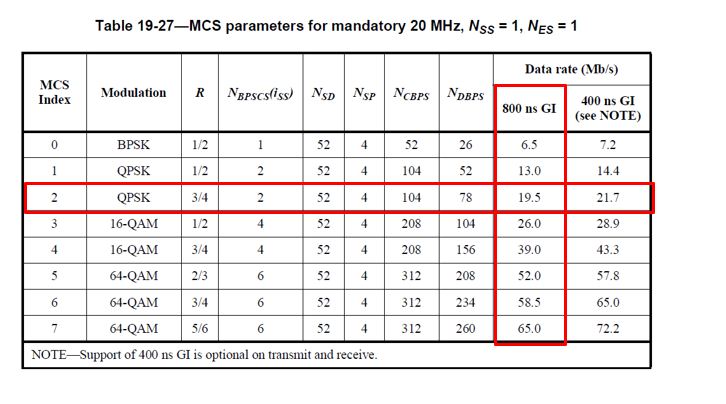

**Based on our current configuration, our link capacity is 19.5 Mbps.**

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower", 0, ...
    "TransmitGain", 0.0, ...
    "MCS",2, ...
    "BeaconInterval",10, ...
    "InitialBeaconOffset",0);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...
    "MCS",2, ...
    "ReceiveGain",0);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

## Create a "sniffer" node

- ¨Passive node listening to all traffic

- "Concatenate" traffic from AP and STA in a single file

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...
    "MCS",2, ...
    "ReceiveGain",0);

SNIFFER = wlanNode(...
    "Name","SNIFFER",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Associate AP with STA

associateStations(AP,STA,"FullBufferTraffic","off");

# Task #1/3 Configure a traffic model 

switch trafficType

    case "QoS_Traffic"

        % Define traffic type

        % Use networkTrafficOnOff() function to configure QoS Traffic
        % Write configuration in a variable named "trafficCfg"
        % Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
        % Note : use the following values to start with
        % onTime = inf
        % OffTime = 0
        % DataRate = 1024*5 kpbs
        % PacketSize = 512
        % Define application data for an easy visualizatoin in Wireshark

        % <enter code below>
        % trafficCfg =

# Task #2/3 Integrate a traffic model into a network node and specify a priority level for the generated traffic. 

        % Add traffic from source to destination
        % Use addTrafficSource() function to add the traffic to simulation
        % Source is "AP"
        % traffic configuration is "trafficCfg"
        % Destination is "STA"
        % "DestinationNode",STA
        % "AccessCategory",0
        % Hint: Click the link below and see the "Syntax" section.

### [Help on adding traffic source to a node ](https://www.mathworks.com/help/wlan/ref/wlannode.addtrafficsource.html)

        % <enter code below>
        %

        trafficCfg_1 = networkTrafficOnOff(...
            "OnTime", inf,...
            "OffTime", 0, ...
            "DataRate",1024*5, ...%kbps
            "PacketSize",513, ...
            "ApplicationData",uint8(0:1:255)',...
            "GeneratePacket",true);


# Task #3/3 Integrate a traffic model into a network node and specify another priority level 

        % Add traffic from source to destination
        % Use trafficCfg_1 for traffic configuration 
        % Use addTrafficSource() function to add the traffic to simulation
        % Source = AP, Destination = STA
        % "AccessCategory",3
       

        % <enter code below>
        %
end

### Wireshark shows packet priority  

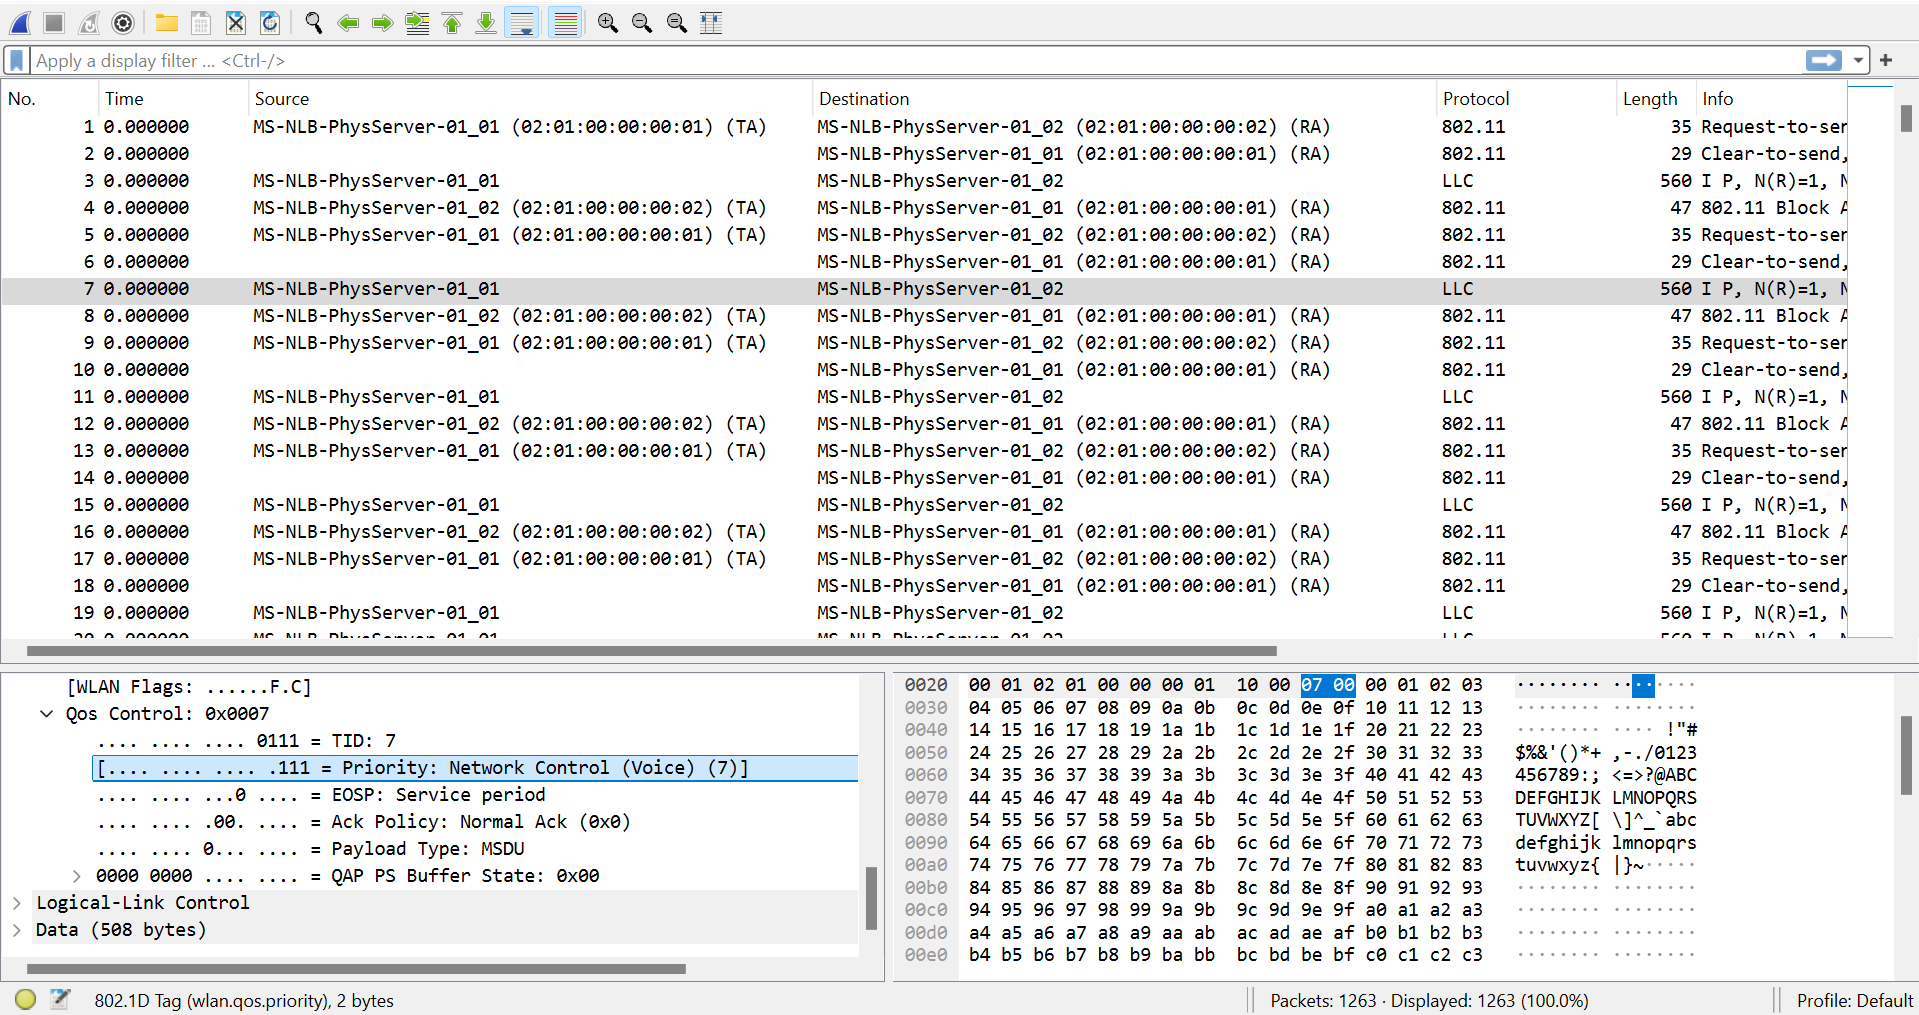

### Create PCAP Capture using the hExportWLANPackets helper Function

- helper functions are early implementations of features that will be fully implemented in the product in future releases

- Provide access to most requested feaures as early as possible

- Gather feedback from early-adopters to help finalize the API

nodes = [AP, STA, SNIFFER];
capturePacketsObj = hExportWLANPackets(nodes, 'pcapng', true);

#### Run the simulation

addNodes(networkSimulator,{AP, STA, SNIFFER})
run (networkSimulator,simulationTime)

### Visualize Results and Statistics

% Navigate to the <Data> folder
% Open SNIFFER PCAP file in Wireshark
% Beacons only (part1), Beacons + traffic (part2)

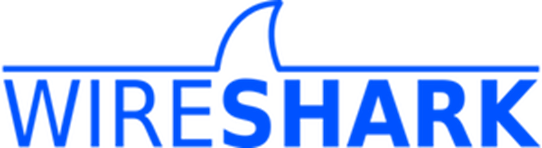

APStatistics  = statistics(AP,"all");
STAStatistics = statistics(STA);

% Use this section to analyze consistency of the data generated in the
% simulation and its visualiation in Wireshark


APStatistics.MAC.AccessCategories.TransmittedDataFrames
delete(capturePacketsObj.PCAPObjList);

**Suggested Experiment:**

- **For downlink traffic, set the data rate of both **`trafficCfg`** and **`trafficCfg_1`** to 15 Mbps.**

- **Visualize the statistics for transmitted packets in each access category.**

- **Open the corresponding packet captures in Wireshark to examine the traffic in detail.**